## **Question:**

What is the window angle and size which would minimize the cost of heating a single-sized manufactured home in Massachussetts?

This optimization of heating cost is particularly relevant to owners and prospective buyers of mobile homes as utilities contribute a large portion to the cost of ownership, and in particular, heating is often necessarily performed by cost-innefective electric heaters.

## **Method:**

Our model can be represented as a series of flows both in and out of the indoor air temperature.

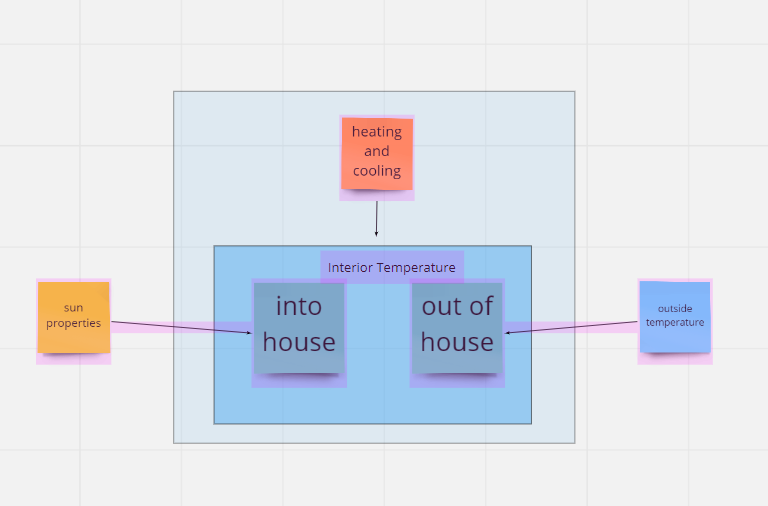

The equations below define our model:


$$\begin{array}{l}
T_o =\mathrm{Outside}\;\mathrm{Temperature}\;\mathrm{at}\;\mathrm{time}\;t\\
T_i =\mathrm{Inside}\;\mathrm{Temperature}\;\mathrm{at}\;\mathrm{time}\;t\\
U_i =\mathrm{Inside}\;\mathrm{Heat}\;\mathrm{at}\;\mathrm{time}\;t\\
R=\mathrm{House}\;\mathrm{Thermal}\;\mathrm{Resistance}\\
A=\mathrm{House}\;\mathrm{Surface}\;\mathrm{Area}
\end{array}$$



$$\begin{array}{l}
S_t =\mathrm{Sun}\;\mathrm{Intensity}\;\mathrm{and}\;\mathrm{Direction}\;\mathrm{Vector}\;\mathrm{at}\;\mathrm{time}\;t\\
W=\mathrm{Window}\;\mathrm{Size}\;\mathrm{and}\;\mathrm{Direction}\;\mathrm{Vector}
\end{array}$$



$$\begin{array}{l}
\Delta P_t =\mathrm{Passive}\;\mathrm{heating}\;\mathrm{through}\;\mathrm{window}\;\mathrm{at}\;\mathrm{time}\;t\\
\Delta L_t =\mathrm{Heat}\;\mathrm{Loss}\;\mathrm{through}\;\mathrm{walls}\\
T_i =\Delta P_t -\Delta L_t \\
\mathrm{Where}\\
\Delta P=S_t \cdot W\\
\Delta L=\frac{\left(T_i \;-T_o \right)\;*A}{R}
\end{array}$$


Control implementation needed

To simplify our model, we assume that all light entering the house through the window is fully absorbed, even though it is likely that some is reflected back. Furthermore, we chose to model the house's thermal resistance as a singular empirically determined amount rather than modelling separate systems for convection and conduction across the wall and into the atmosphere. Finally, we did not model the change in thermal resistance that a greater or lesser sized window would incur.

First, we defined initial state.

tAir = 294;
tOutside = 278;
specAir = 1006;     %Joules/(kg*K)

densAir = 1.225;    %kg / m^3
volumeAir = 299;    %m^3 Standard volume of midsized manufactured home (4.27x17.06x4.11)
massAir = densAir * volumeAir;  %kg


Citations needed

Empirical NOAA data needed

We then created rate functions for both the Sunlight and Heat loss energy flows:

t0 = 0;
tend = 1;      %days

dt = 1/(24*12);

numSteps = (tend - t0) / dt;
T = zeros(numSteps + 1, 1);

U = zeros(size(T));
U(1) = temperatureToEnergy(tAir, massAir, specAir);
for i = 1:numSteps
    % heat lost in watts (J/s)
    heatLost = heatLoss(energyToTemperature(U(i), massAir, specAir), tOutside);
    % convert W to W days
    dudt = heatLost*dt*3600*12;
    T(i+1) = T(i) + dt;
    U(i+1) = U(i) + dudt;
end


Sunlight implementation needed

Results: